# Data Acquisition System

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-01-06

### Sampling

clear; clc ; close all;

syms t   

f = 1;
y = sin(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
ncyle = 2;
Fsa = 10000; % # of samples per a second
ta = 0:1/Fsa:ncyle;
ya = subs(y, t, ta);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(311); plot(ta,ya,'-b', 'linewidth', 2);hold on;
legend('Analog'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

Fsd = 5; % # of samples per a second
td = 0:1/Fsd:ncyle;
yd = subs(y, t, td);

subplot(312); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td,yd,'or','linewidth',2); hold off;
legend('Analog', 'digital'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

subplot(313); plot(td,yd,'or','linewidth',2); 
legend('digital'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

### Aliasing

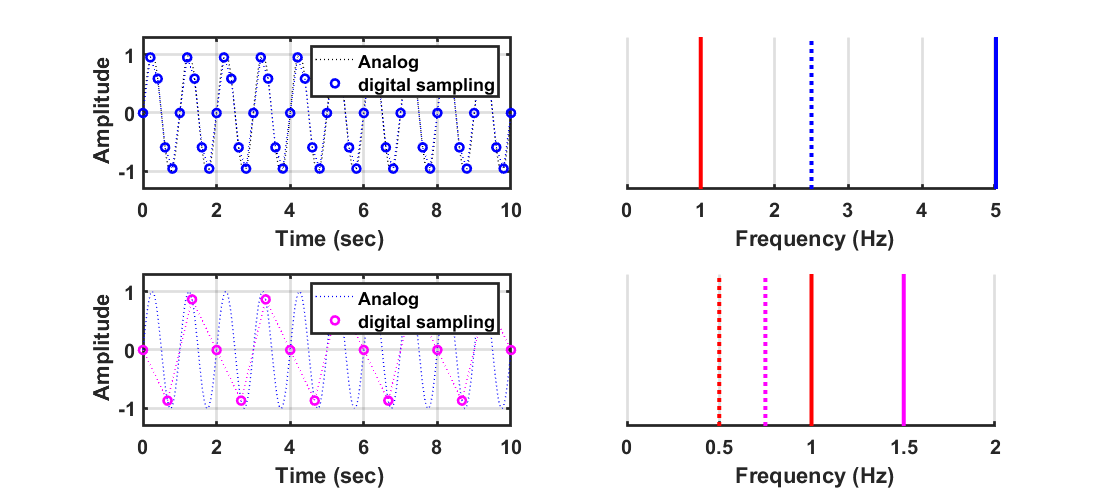

clear; clc ; close all;

syms t   

f = 1;
y = sin(2*pi*f*t);

% this signal is assumed to be analog (very high sampling rate). 
ncyle = 10;
Fsa = 1000; % # of samples per a second
ta = 0:1/Fsa:ncyle;
ya = subs(y, t, ta); 

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 500]);

Fsd1 = 5; % # of samples per a second
td1 = 0:1/Fsd1:ncyle;
yd1 = subs(y, t, td1);

subplot(221); plot(ta,ya,':k', 'linewidth', 1); hold on;
plot(td1,yd1,'ob','linewidth',2); 
plot(td1,yd1,':b','linewidth',1); hold off;
legend('Analog', 'digital sampling'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

subplot(222);
line([Fsd1 Fsd1], [0 1] , 'linewidth', 3, 'color', 'b');  hold on; % sampling frequency 
line([Fsd1/2 Fsd1/2], [0 1] , 'linewidth', 3, 'color', 'b', 'lineStyle', ':'); % Nyquist frequency
line([f f], [0 1] , 'linewidth', 3, 'color', 'r'); % frequency of interest
hold off; axis tight;grid on;
ylim([0 1]);set(gca, 'YTick', [])
xlabel('\bf Frequency (Hz)'); xlim([0 5])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold','YColor','none');

Fsd2 = 1.5; % # of samples per a second
td2 = 0:1/Fsd2:ncyle;
yd2 = subs(y, t, td2);

subplot(223); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td2,yd2,'om','linewidth',2); 
plot(td2,yd2,':m','linewidth',1); hold off;
legend('Analog', 'digital sampling');
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

subplot(224); hold on;
line([Fsd2 Fsd2], [0 1] , 'linewidth', 3, 'color', 'm'); 
line([Fsd2/2 Fsd2/2], [0 1] , 'linewidth', 3, 'color', 'm', 'lineStyle', ':'); 
line([f f], [0 1] , 'linewidth', 3, 'color', 'r'); 

freq_samp = Fsd2/2 - abs(f-Fsd2/2);
line([freq_samp freq_samp], [0 1] , 'linewidth', 3, 'color', 'r', 'lineStyle', ':'); 

hold off; axis tight;grid on;
ylim([0 1]);set(gca, 'YTick', [])
xlabel('\bf Frequency (Hz)'); xlim([0 2])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold','YColor','none');

### Spatial Aliasing

nCycle = 10;
orgFreq = 120;
x = linspace(0,nCycle,nCycle*orgFreq); 
sig1 = sin(2*pi*x);

img1 = (repmat(sig1, [nCycle*orgFreq,1])+1)/2;

sig2 = sig1(1:orgFreq/5:end);
sig2 = repelem(sig2, orgFreq/5);
img2 = (repmat(sig2, [nCycle*orgFreq,1])+1)/2;

sig3 = sig1(1:orgFreq/1.5:end);
sig3 = repelem(sig3, orgFreq/1.5);
img3 = (repmat(sig3, [nCycle*orgFreq,1])+1)/2;

figure(10)
subplot(131);imshow(img1)
subplot(132);imshow(img2)
subplot(133);imshow(img3)

### Oversampling

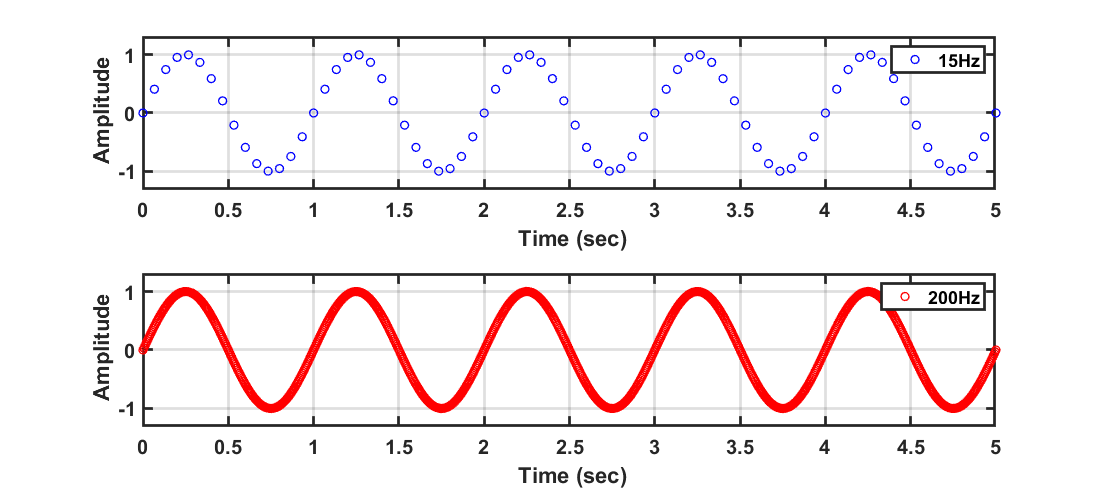

clear; clc ; close all;

% analog signal (very high sampling frequency)
syms t

f = 1;
y = sin(2*pi*f*t);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 500]);

ncycle = 5;
Fsd1 = 15; % # of samples per a second
td1 = 0:1/Fsd1:ncycle;
yd1 = subs(y, t, td1);

subplot(211); plot(td1,yd1,'ob','linewidth',1);
legend('15Hz'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

Fsd2 = 200; % # of samples per a second
td2 = 0:1/Fsd2:ncycle;
yd2 = subs(y, t, td2);

subplot(212); plot(td2,yd2,'or','linewidth',1);
legend('200Hz'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

### Quantization

clear; clc ; close all;

% 3bit A/D converter
sig = rand(1000, 1)*8-4;

sig_digit = interp1(-4:4,-4:4, sig, 'nearest');

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 500]);

plot(sig,sig_digit,'ob', 'linewidth', 1); hold on;
plot(-4:4,-4:4,':k'); hold off;
axis square;grid on;

set(gca, 'XTick', -4:4, 'YTick', -4:4)
xlabel('\bf Analogue voltage'); 
ylabel('\bf Digital voltage'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')


syms t

f = 1;
ampt = 10;
y = sin(2*pi*f*t)*ampt;

fig2 = figure(2);
set(fig2,'Position', [100 100 1100 700]);

% this signal is assumed to be analog. 
ncycle = 2;
Fsa = 1000; % # of samples per a second
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta);

Fsd1 = 10; % # of samples per a second
td1 = 0:1/Fsd1:ncycle;
yd1 = subs(y, t, td1);

subplot(221); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td1,yd1,':r','linewidth',2);
plot(td1,yd1,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-12 12]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

yd1_digit = interp1(-10:2.5:10,-10:2.5:10, double(yd1), 'nearest');

subplot(222); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td1,yd1_digit,':r','linewidth',2);
plot(td1,yd1_digit,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-12 12]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold', 'YTick', -10:2.5:10)


subplot(223); plot(ta,ya/5,':b', 'linewidth', 1); hold on;
plot(td1,yd1/5,':r','linewidth',2);
plot(td1,yd1/5,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-12 12]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

resol = 20/8;
yd1_digit = interp1(-10:resol:10,-10:resol:10, double(yd1/5), 'nearest');

subplot(224); plot(ta,ya/5,':b', 'linewidth', 1); hold on;
plot(td1,yd1_digit,':r','linewidth',2);
plot(td1,yd1_digit,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-12 12]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold', 'YTick', -10:2.5:10)



### Clipping

fig3 = figure(3);
set(fig3,'Position', [100 100 1100 700]);

y = sin(w*t)*2;
% this signal is assumed to be analog. 
ncyle = 2;
Fsa = 1000; % # of samples per a second
ta = 0:1/Fsa:ncyle;
ya = subs(y, t, ta);

Fsd1 = 10; % # of samples per a second
td1 = 0:1/Fsd1:ncyle;
yd1 = subs(y, t, td1);

subplot(221); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td1,yd1,':r','linewidth',2);
plot(td1,yd1,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-2.2 2.2]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

resol = 4/8;
yd1_digit = interp1(-2:resol:2,-2:resol:2, double(yd1), 'nearest');

subplot(222); plot(ta,ya,':b', 'linewidth', 1); hold on;
plot(td1,yd1_digit,':r','linewidth',2);
plot(td1,yd1_digit,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-2.2 2.2]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold', 'YTick', -2:resol:2)

subplot(223); plot(ta,ya*1.5,':b', 'linewidth', 1); hold on;
plot(td1,yd1*1.5,':r','linewidth',2);
plot(td1,yd1*1.5,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-3.2 3.2]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold', 'YTick', -3:3)

resol = 4/8;
yd1_digit = interp1(-2:resol:2,-2:resol:2, double(yd1*1.5), 'nearest','extrap');

subplot(224); plot(ta,ya*1.5,':b', 'linewidth', 1); hold on;
plot(td1,yd1_digit,':r','linewidth',2);
plot(td1,yd1_digit,'or','linewidth',2); hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-3.2 3.2]);
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold', 'YTick', -2:resol:2)

### Demo: Vibration Measurement Using Smart Phones

clear; clc ; close all;
load vibration_1Hz

Fs = numel(time)/time(end);

% time = time(50:end-10);
% zvib = zvib(50:end-10);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(211); plot(time,zvib,'b', 'linewidth', 1);
axis tight;grid on;
ylabel('\bf Acceleration (m/s^2)'); 
xlabel('\bf Time (sec)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')
% 
L = length(zvib);
nfft = 2^nextpow2(L);

Y = fft(zvib,nfft);

P2 = abs(Y/L);
P1 = P2(1:nfft/2+1);
P1(2:end-1) = 2*P1(2:end-1);

subplot(212); plot(0:(Fs/nfft):(Fs/2-Fs/nfft),P1(1:nfft/2),'b');
xlabel('f (Hz)'); xlim([0 10])
ylabel('Amplitdue (f)'); 
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

% figure(2);
% plot(time,zraw,'b', 'linewidth', 1);
% axis tight;grid on;
% ylabel('\bf Acceleration (m/s^2)'); ylim([-100 100])
% xlabel('\bf Time (sec)'); 
% set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')